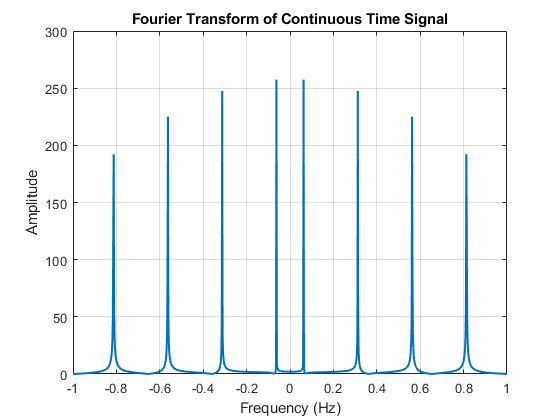

clc;
clear;
close all;
fs=2;
t=-256:1/fs:256;
f=[1/16,5/16,9/16,13/16];
x=0;
for i=1:4
x=x+cos(2*pi*f(i)*t);
end

X=1/fs*fftshift(fft(x));
f_axis1 = linspace(-fs / 2, fs / 2, length(X));
figure('Name', 'Fourier Transform of Continuous Time Signal');
plot(f_axis1, abs(X), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Fourier Transform of Continuous Time Signal');
xlim([-1, 1]);
grid on;

coef_anal=xlsread('C:\Users\LOMUZG\Downloads\filters.xls')

coef_anal =     0.0183   -0.0023   -0.0136   -0.0036   -0.0124    0.0174    0.0567   -0.0071   -0.0421   -0.0654   -0.0740   -0.0325    0.0562    0.1458    0.2223    0.2546    0.2417    0.1728    0.0669    0.0167   -0.0405   -0.0282    0.0051    0.0232    0.0431    0.0049    0.0028   -0.0082   -0.0111   -0.0013   -0.0146    0.0080
    0.0061   -0.0127    0.0179    0.0337   -0.0121   -0.0364   -0.0215   -0.0570   -0.0929    0.0484    0.2116    0.1327   -0.1379   -0.2624   -0.0564    0.2028    0.1704   -0.0395   -0.0851   -0.0073    0.0103   -0.0530   -0.0319    0.0331    0.0590    0.0002   -0.0018    0.0188   -0.0136    0.0099   -0.0216    0.0203
    0.0030   -0.0007   -0.0117   -0.0130    0.0222    0.0137   -0.0083   -0.0089   -0.0544    0.1273   -0.0277   -0.1949    0.1987    0.0803   -0.2664    0.1228    0.1303   -0.1786    0.0123    0.0666   -0.0115    0.0067   -0.0466    0.0519    0.0679   -0.0403    0.0069   -0.0013   -0.0159    0.0165   -0.0349    0.0254
    0.0333   -0.0274   -0

coef_synt=xlsread('C:\Users\LOMUZG\Downloads\filters.xls','Sheet2')

coef_synt =     0.0234   -0.0501   -0.0038   -0.0398   -0.0389    0.0122    0.0092    0.1528    0.0922    0.0635   -0.1034   -0.1656    0.0312    0.2971    0.7066    0.9285    0.9862    0.9102    0.5682    0.2370   -0.1633   -0.2746   -0.2592   -0.1151   -0.0303    0.2053    0.0624   -0.0473   -0.0113   -0.0523   -0.0088    0.0780
    0.0658   -0.0617    0.0376   -0.0407    0.0763   -0.0140    0.0089    0.2067    0.1413   -0.1314   -0.2136    0.0452   -0.0549   -0.3948   -0.1611    0.6251    0.7318   -0.1687   -1.0657   -0.5194    0.5050    0.7999    0.1866   -0.3894   -0.2065   -0.0789   -0.1162   -0.0250    0.1342    0.0723   -0.0505    0.0202
    0.0840   -0.1137    0.0614   -0.0518    0.0029    0.0078   -0.1462    0.2435    0.1970   -0.1648    0.0305   -0.0334    0.2657    0.0401   -0.7117    0.4799    0.4371   -1.0315    0.2993    0.7788   -0.7734   -0.1614    0.5029   -0.2373   -0.0026   -0.0250    0.0453    0.0732   -0.0611   -0.0484   -0.0009    0.0057
   -0.0345    0.0422   -0

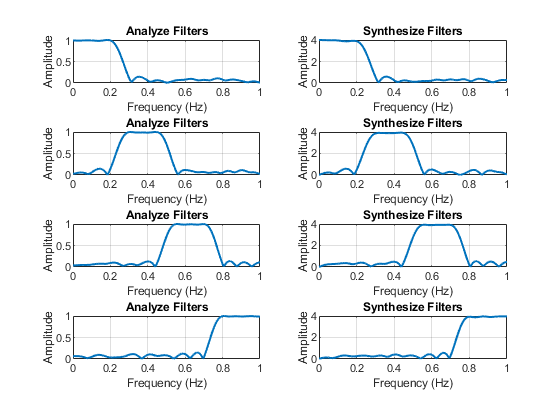

n=1:size(coef_anal,2);
w_axis = linspace(0, pi, 1e3);
DTFT_coef_anal = coef_anal * exp(-1j * n' * w_axis);
DTFT_coef_synt = coef_synt * exp(-1j * n' * w_axis);
figure('Name', 'Amplitude of  filters');
subplot(421);
plot(w_axis/pi, abs(DTFT_coef_anal(1,:)), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Analyze Filters');
xlim([-0 1]);
grid on;
subplot(423);
plot(w_axis/pi, abs(DTFT_coef_anal(2,:)), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Analyze Filters');
xlim([-0 1]);
grid on;
subplot(425);
plot(w_axis/pi, abs(DTFT_coef_anal(3,:)), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Analyze Filters');
xlim([-0 1]);
grid on;
subplot(427);
plot(w_axis/pi, abs(DTFT_coef_anal(4,:)), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Analyze Filters');
xlim([-0 1]);
grid on;
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Analyze Filters');
xlim([-0 1]);
grid on;
subplot(422);
plot(w_axis/pi, abs(DTFT_coef_synt(1,:)), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Synthesize Filters');
xlim([-0 1]);
grid on;
subplot(424);
plot(w_axis/pi, abs(DTFT_coef_synt(2,:)), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Synthesize Filters');
xlim([-0 1]);
grid on;
subplot(426);
plot(w_axis/pi, abs(DTFT_coef_synt(3,:)), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Synthesize Filters');
xlim([-0 1]);
grid on;
subplot(428);
plot(w_axis/pi, abs(DTFT_coef_synt(4,:)), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Synthesize Filters');
xlim([-0 1]);
grid on;
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Synthesize Filters');
xlim([-0 1]);
grid on;

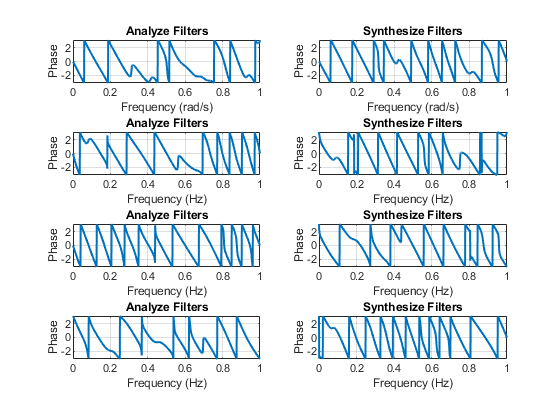

figure('Name', 'Phase of analyze filters')
subplot(421);
plot(w_axis/pi, angle(DTFT_coef_anal(1,:)), 'LineWidth', 1.5);
xlabel('Frequency (rad/s)');
ylabel('Phase');
title('Analyze Filters');
xlim([-0 1]);
grid on;
subplot(423);
plot(w_axis/pi, angle(DTFT_coef_anal(2,:)), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Phase');
title('Analyze Filters');
xlim([-0 1]);
grid on;
subplot(425);
plot(w_axis/pi, angle(DTFT_coef_anal(3,:)), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Phase');
title('Analyze Filters');
xlim([-0 1]);
grid on;
subplot(427);
plot(w_axis/pi, angle(DTFT_coef_anal(4,:)), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Phase');
title('Analyze Filters');
xlim([-0 1]);
grid on;
xlabel('Frequency (Hz)');
ylabel('Phase');
title('Analyze Filters');
xlim([-0 1]);
grid on;
subplot(422);
plot(w_axis/pi, angle(DTFT_coef_synt(1,:)), 'LineWidth', 1.5);
xlabel('Frequency (rad/s)');
ylabel('Phase');
title('Synthesize Filters');
xlim([-0 1]);
grid on;
subplot(424);
plot(w_axis/pi, angle(DTFT_coef_synt(2,:)), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Phase');
title('Synthesize Filters');
xlim([-0 1]);
grid on;
subplot(426);
plot(w_axis/pi, angle(DTFT_coef_synt(3,:)), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Phase');
title('Synthesize Filters');
xlim([-0 1]);
grid on;
subplot(428);
plot(w_axis/pi, angle(DTFT_coef_synt(4,:)), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Phase');
title('Synthesize Filters');
xlim([-0 1]);
grid on;
xlabel('Frequency (Hz)');
ylabel('Phase');
title('Synthesize Filters');
xlim([-0 1]);
grid on;

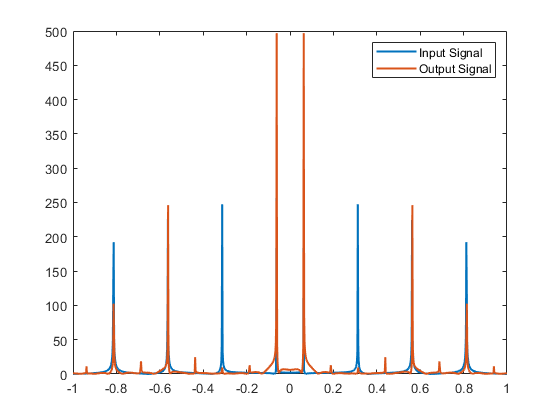

x_anal1=filter(coef_anal(1,:),1,x);
x_anal2=filter(coef_anal(2,:),1,x);
x_anal3=filter(coef_anal(3,:),1,x);
x_anal4=filter(coef_anal(4,:),1,x);


x1=downsample(x_anal1,4);
x2=downsample(x_anal2,4);
x3=downsample(x_anal3,4);
x4=downsample(x_anal4,4);

x1=2*x1;
x2=0*x2;
x3=1*x3;
x4=0.5*x4;

x1=upsample(x1,4);
x2=upsample(x2,4);
x3=upsample(x3,4);
x4=upsample(x4,4);


x_synt1=filter(coef_synt(1,:),1,x1);
x_synt2=filter(coef_synt(2,:),1,x2);
x_synt3=filter(coef_synt(3,:),1,x3);
x_synt4=filter(coef_synt(4,:),1,x4);

x_reconst=x_synt1+x_synt2+x_synt3+x_synt4;
X_reconst=1/fs*fftshift(fft(x_reconst));
f_axis2 = linspace(-fs / 2, fs / 2, length(X_reconst));
figure('Name', 'Fourier Transform of Continuous Time Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Fourier Transform of Continuous Time Signal');
xlim([-1, 1]);
grid on;
plot(f_axis1, abs(X), 'LineWidth', 1.5);
hold on;
plot(f_axis2, abs(X_reconst),'LineWidth', 1.5);

legend('Input Signal','Output Signal')